# **HW3 Program Assignment**

**By: 105060012 張育菘**

## P8

Compute and plot the phase response using the functions freqz, angle, phasez, unwrap, and phasedelay for the following systems:

(a) $y\left\lbrack n\right\rbrack =x\left\lbrack n-15\right\rbrack$

close all; clear;
fprintf('8(a)\n');

8(a)


By "freqz"


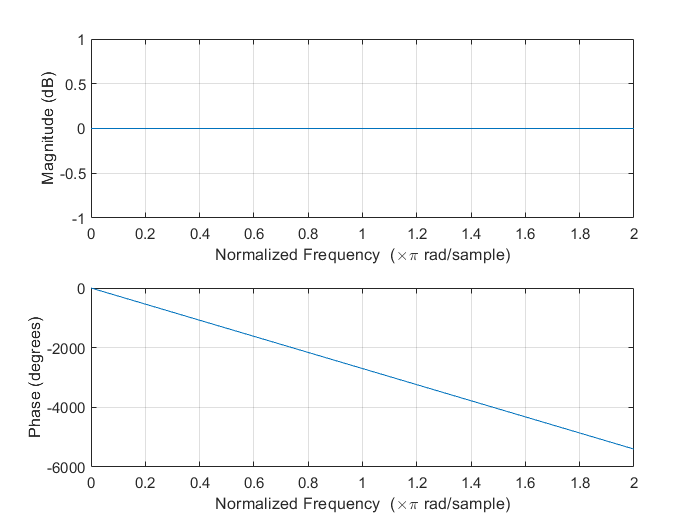


om = linspace(0, 2*pi, 1000); 
b = zeros(1, 16); b(16) = 1; a = [1];
fprintf('By "freqz"\n'); freqz(b, a, om)


H1 = freqz(b, a, om);
figure;
fprintf('By "angle"\n');

By "angle"


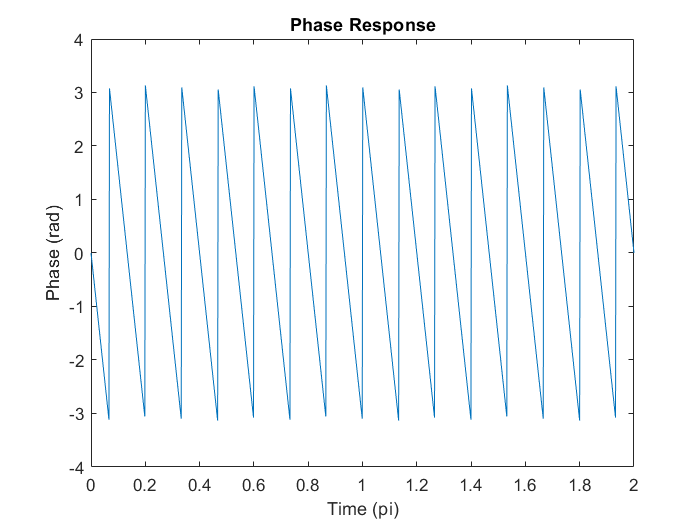

plot(om/pi, angle(H1));
title('Phase Response');
ylabel('Phase (rad)');
xlabel('Time (pi)');

By "phasez"


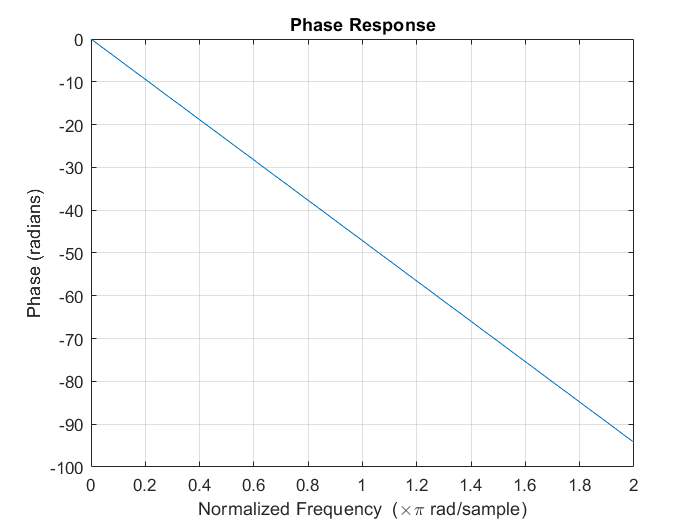


fprintf('By "phasez"\n'); phasez(b, a, om)


figure;
fprintf('By "unwrap"\n');

By "unwrap"


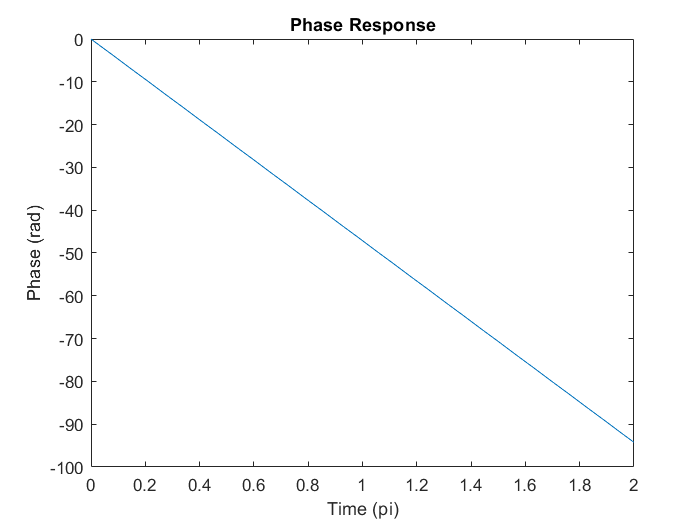

plot(om/pi, unwrap(angle(H1)));
title('Phase Response');
ylabel('Phase (rad)');
xlabel('Time (pi)');

By "phasedelay"


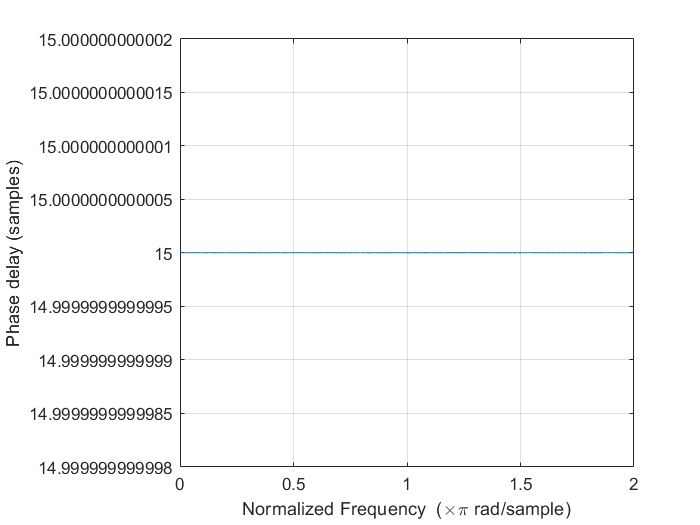


fprintf('By "phasedelay"\n'); phasedelay(b, a, om)

(b) $H\left(z\right)=\frac{1+1\ldotp 655{\mathrm{𝑧}}^{-1} +1\ldotp 655{\mathrm{𝑧}}^{-2} +{\mathrm{𝑧}}^{-3} }{1-1\ldotp 57{\mathrm{𝑧}}^{-1} +1\ldotp 264{\mathrm{𝑧}}^{-2} -0\ldotp 4{\mathrm{𝑧}}^{-3} }$

fprintf('8(b)\n');

8(b)


By "freqz"


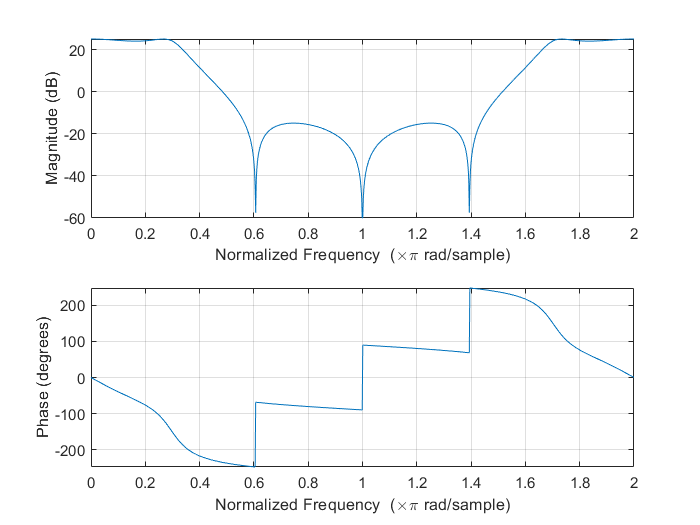


om = linspace(0, 2*pi, 1000); 
b = [1 1.655 1.655 1]; a = [1 -1.57 1.264 -0.4];
fprintf('By "freqz"\n'); freqz(b, a, om)


H1 = freqz(b, a, om);
figure;
fprintf('By "angle"\n');

By "angle"


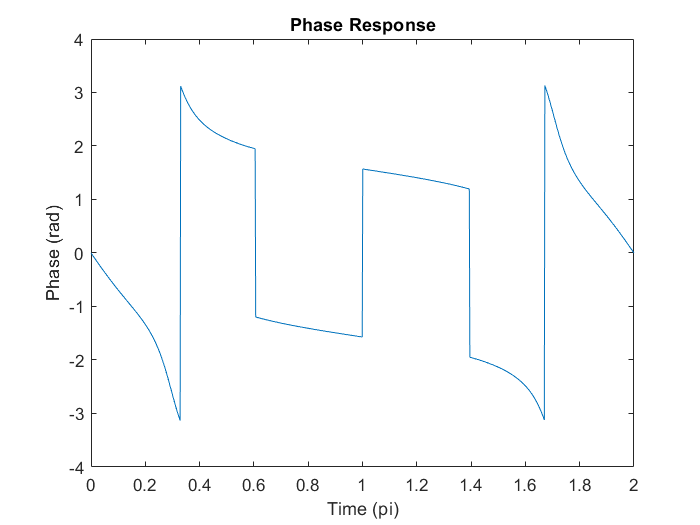

plot(om/pi, angle(H1));
title('Phase Response');
ylabel('Phase (rad)');
xlabel('Time (pi)');

By "phasez"


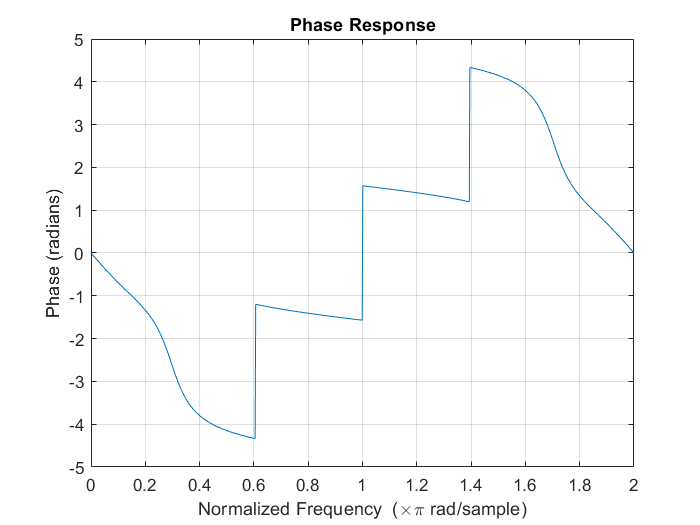


fprintf('By "phasez"\n'); phasez(b, a, om)


figure;
fprintf('By "unwrap"\n');

By "unwrap"


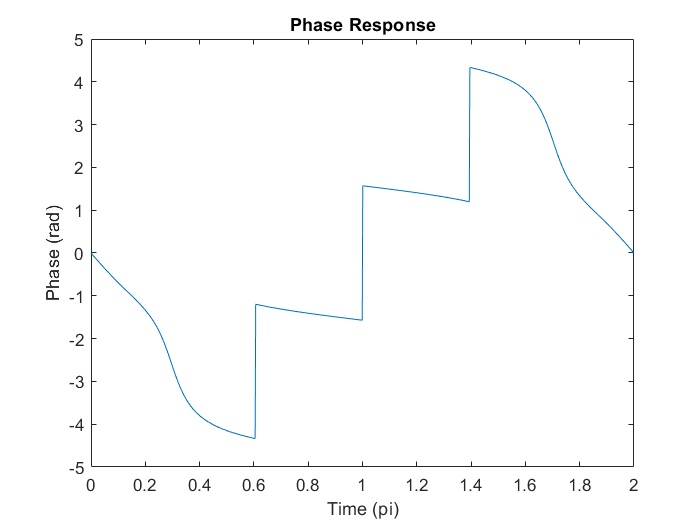

plot(om/pi, unwrap(angle(H1)));
title('Phase Response');
ylabel('Phase (rad)');
xlabel('Time (pi)');

By "phasedelay"


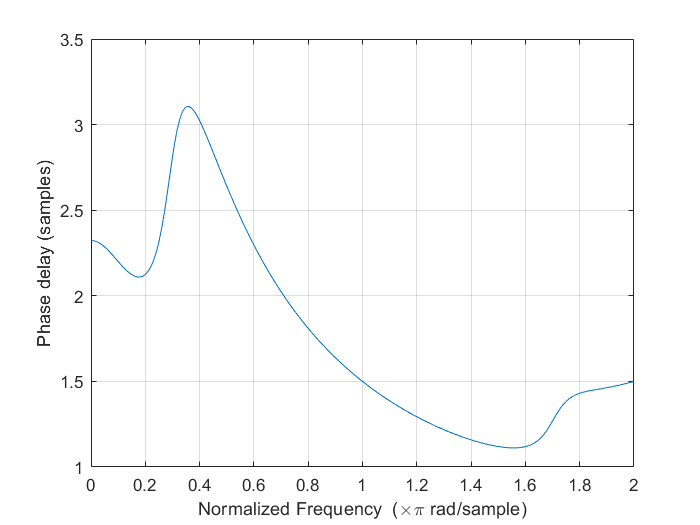


fprintf('By "phasedelay"\n'); phasedelay(b, a, om)

## P9

According to problem 2 in paper assignment, plot magnitude response, phase response and group-delay response for each of the systems.

close all; clear;
fprintf('9\n');

9


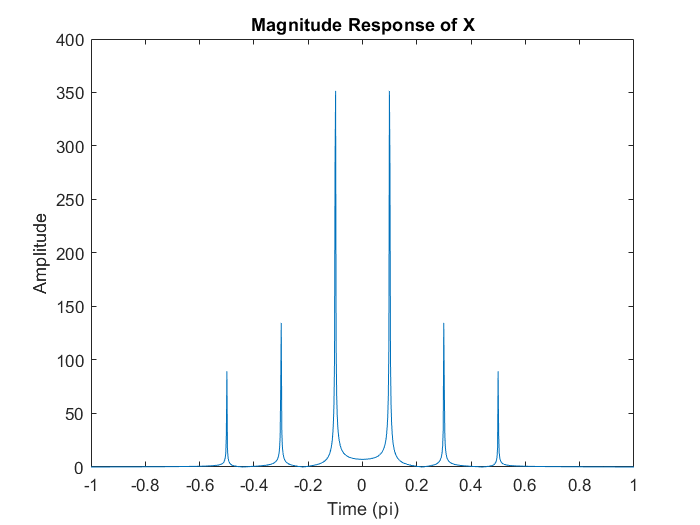


om=linspace(-pi, pi, 1000);
n = linspace(0,1000,1001);
x = sin(0.1*pi*n)+(1/3)*sin(0.3*pi*n)+0.2*sin(0.5*pi*n);
X = freqz(x,1,om);
gd = grpdelay(x,1,om);

figure; plot(om/pi, abs(X));
title('Magnitude Response of X');
ylabel('Amplitude');
xlabel('Time (pi)');

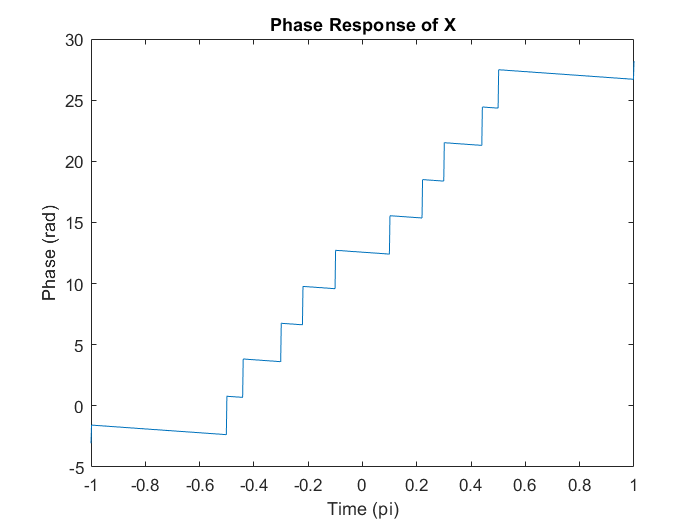

figure; plot(om/pi, unwrap(angle(X)));
title('Phase Response of X');
ylabel('Phase (rad)');
xlabel('Time (pi)');

(a) $\mathrm{h}{\left[\mathrm{n}\right]}=\left\lbrace 1_{\mathrm{n}=0} ,-2,3,-4,0,4,-3,2,-1\right\rbrace$ 

fprintf('9(a)\n');

9(a)


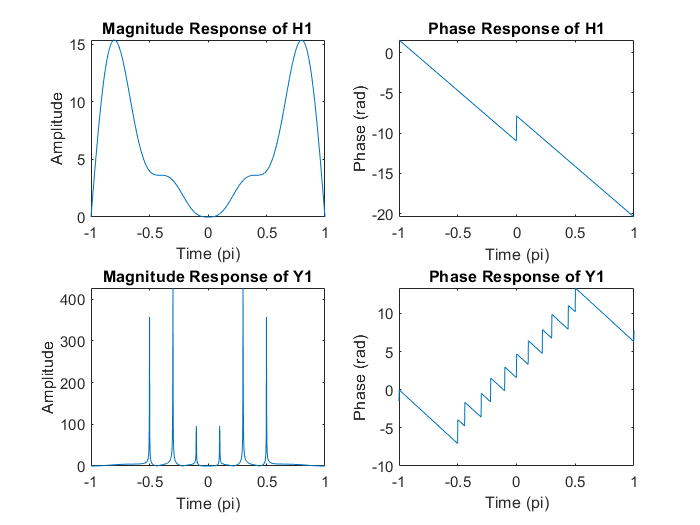


h1 = [1 -2 3 -4 0 4 -3 2 -1]; % start from n=0
H1 = freqz(h1,1,om); H1 = exp(-j*om*0).*H1;
gd1 = grpdelay(h1, 1, om);

figure; 
subplot(2,2,1); plot(om/pi, abs(H1));
title('Magnitude Response of H1');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,2); plot(om/pi, unwrap(angle(H1)));
title('Phase Response of H1');
ylabel('Phase (rad)');
xlabel('Time (pi)');
Y1 = X.*H1;
subplot(2,2,3); plot(om/pi, abs(Y1));
title('Magnitude Response of Y1');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,4); plot(om/pi, unwrap(angle(Y1)));
title('Phase Response of Y1');
ylabel('Phase (rad)');
xlabel('Time (pi)');

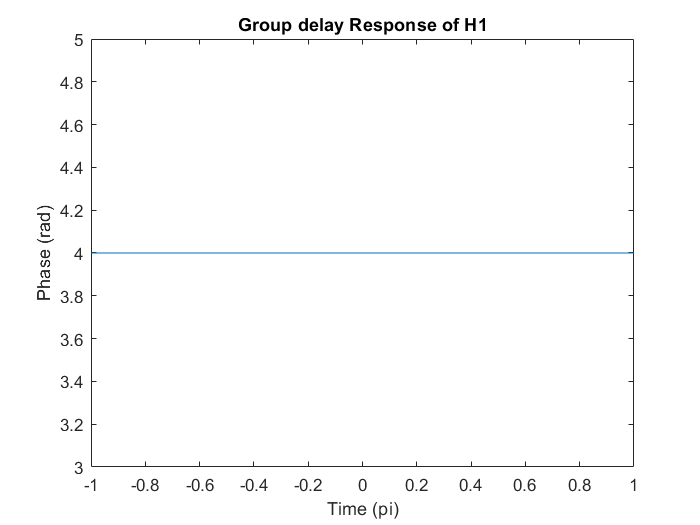


figure; plot(om/pi, gd1);
title('Group delay Response of H1')
ylabel('Phase (rad)');
xlabel('Time (pi)');

(b) $\mathrm{y}{\left[\mathrm{n}\right]}=10\mathrm{x}\left\lbrack \mathrm{n}-10\right\rbrack$

fprintf('9(b)\n');

9(b)


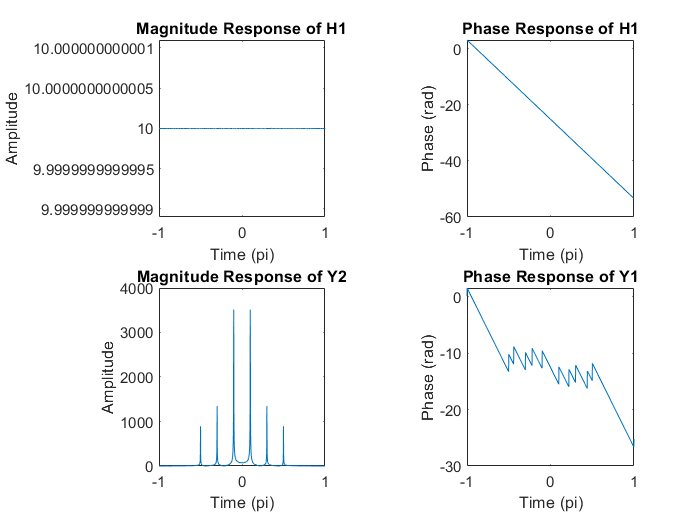


b = zeros(1, 10); b(10) = 10;
a = [1];
H2 = freqz(b,a,om);
gd2 = grpdelay(b, a, om);

figure; 
subplot(2,2,1); plot(om/pi, abs(H2));
title('Magnitude Response of H1');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,2); plot(om/pi, unwrap(angle(H2)));
title('Phase Response of H1');
ylabel('Phase (rad)');
xlabel('Time (pi)');
Y2 = X.*H2; 
subplot(2,2,3); plot(om/pi, abs(Y2));
title('Magnitude Response of Y2');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,4); plot(om/pi, unwrap(angle(Y2)));
title('Phase Response of Y1');
ylabel('Phase (rad)');
xlabel('Time (pi)');

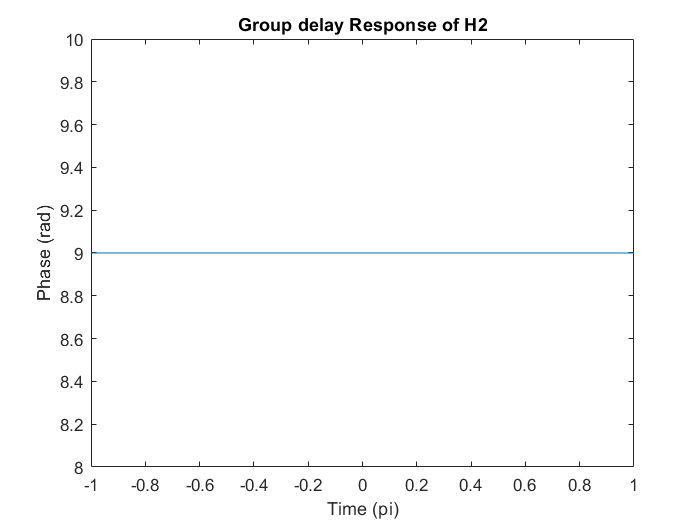


figure; plot(om/pi, gd2);
title('Group delay Response of H2')
ylabel('Phase (rad)');
xlabel('Time (pi)');

## P10

MATLAB provides a function called polystab that stabilizes the given polynomial with respect to the unit circle, that is, it reﬂects those roots which are outside the unit-circle into those that are inside the unit circle but with the same angle. 

Using this function, convert the following systems into minimum-phase and maximum-phase systems. Verify your answers using a pole-zero plot for each system(plot minimum-phase and maximum-phase systems for each question).

(a) $H\left(z\right)=\frac{{\textrm{𝑧}}^2 +2\textrm{𝑧}+0\ldotp 75}{\;{\textrm{𝑧}}^2 -0\ldotp 5\textrm{𝑧}}$

Ans:

zero = -1/2 & -3/2, pole = 1/2

For Hmin: zero = -1/2 & -2/3, pole = 1/2


$$\Longrightarrow H_{\mathrm{min}} =\frac{\left(1+\frac{1}{2}z^{-1} \right)\left(1+\frac{2}{3}z^{-1} \right)}{\left(1-\frac{1}{2}z^{-1} \right)}=\frac{1+\frac{7}{6}z^{-1} +\frac{1}{3}z^{-2} }{1-\frac{1}{2}z^{-1} }$$


For Hmax: zero = -2 & -3/2, pole = 1/2


$$\Longrightarrow H_{\mathrm{max}} =\frac{\left(1+\frac{1}{2}z\right)\left(1+\frac{2}{3}z\right)}{\left(1-\frac{1}{2}z^{-1} \right)}=\frac{1+\frac{7}{6}z^1 +\frac{1}{3}z^2 }{1-\frac{1}{2}z^{-1} }$$


close all; clear;
fprintf('10(a)\n');

10(a)


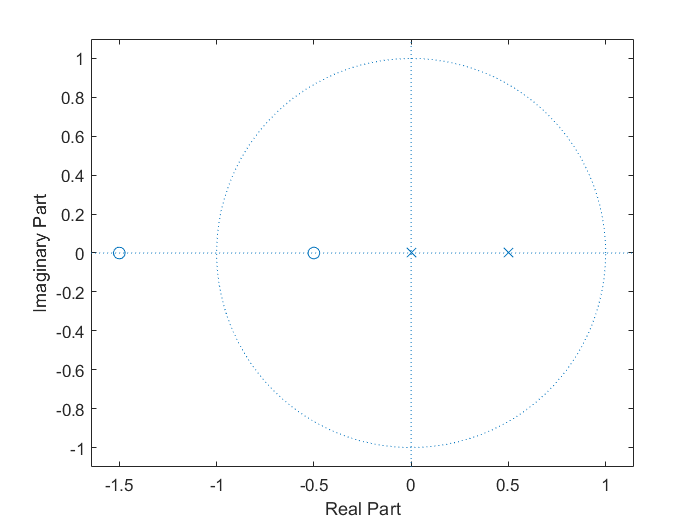


b = [1 2 0.75]; a = [1 -0.5];
zplane(b, a);

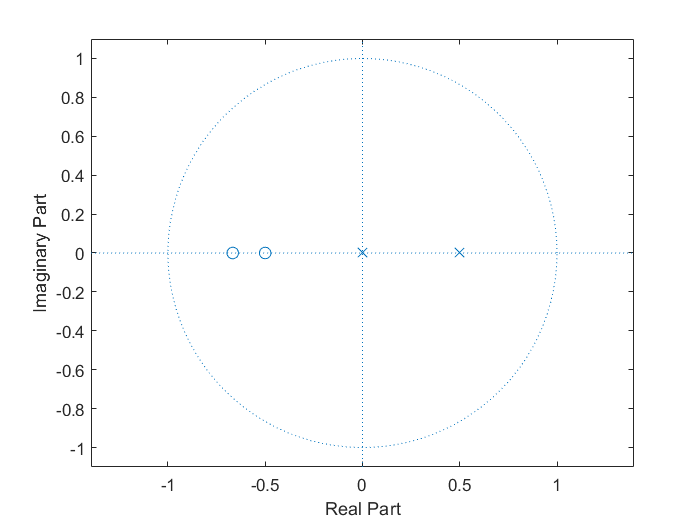


b_min = polystab(b); a_min = polystab(a);
zplane(b_min, a_min);

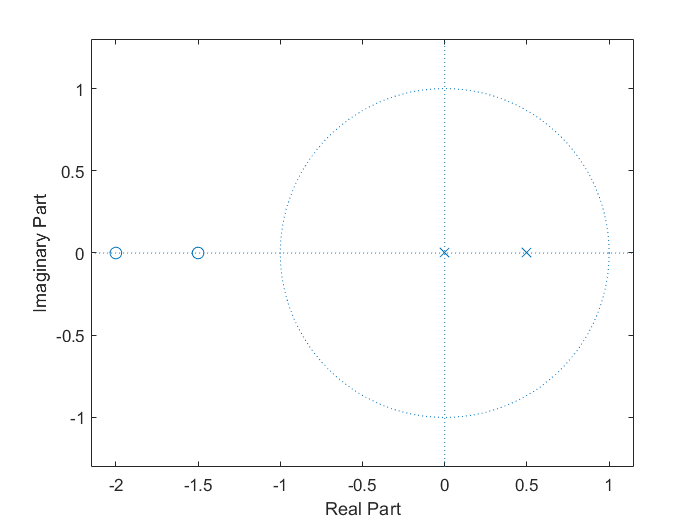


b_max = fliplr(b_min); a_max = a_min;
zplane(b_max, a_max);

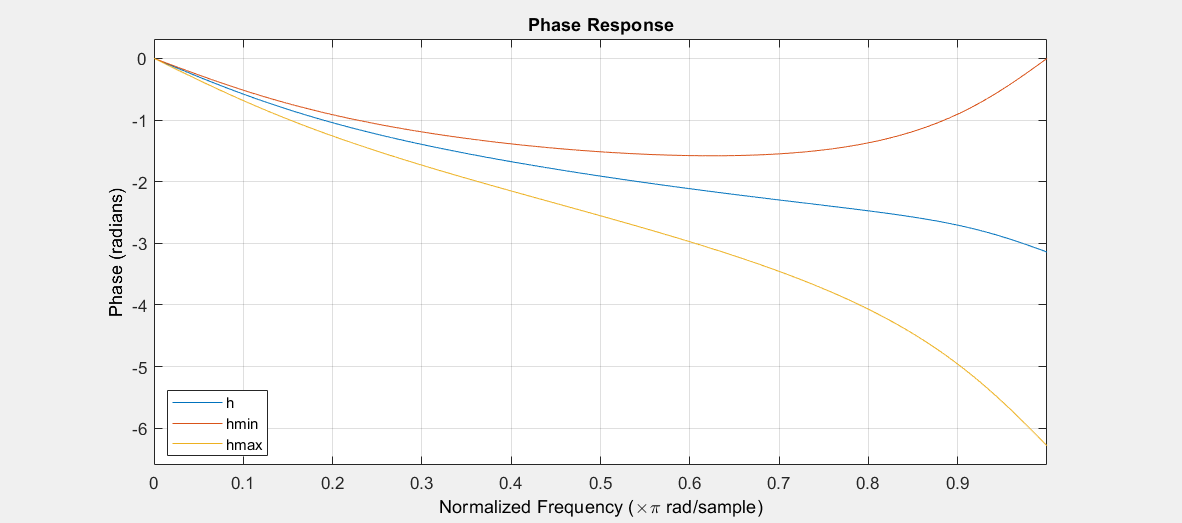


hfvt = fvtool(b, a, b_min, a_min, b_max, a_max,'Analysis','phase');
legend(hfvt,'h','hmin','hmax');

(b) $H\left(z\right)=\frac{1-2\ldotp 4142{\mathrm{𝑧}}^{-1} +2\ldotp 4142{\mathrm{𝑧}}^{-2} -{\mathrm{𝑧}}^{-3} }{1-1\ldotp 8{\mathrm{𝑧}}^{-1} +1\ldotp 62{\mathrm{𝑧}}^{-2} +0\ldotp 729{\mathrm{𝑧}}^{-3} }$

fprintf('10(b)\n');

10(b)


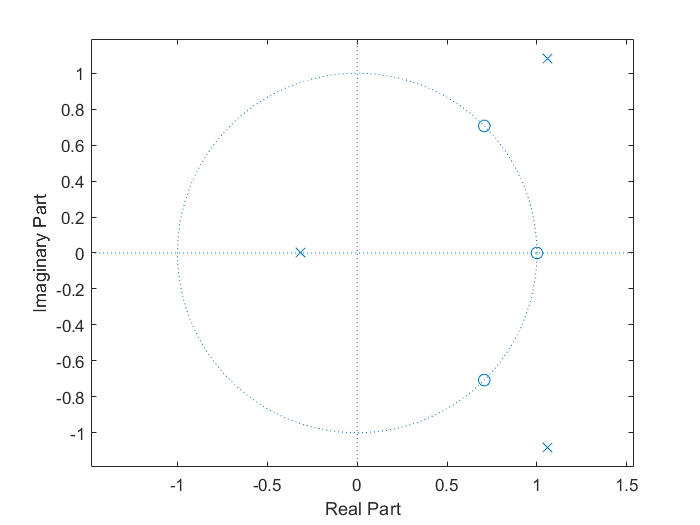


b = [1 -2.4142 2.4142 -1]; a = [1 -1.8 1.62 0.729];
zplane(b, a);

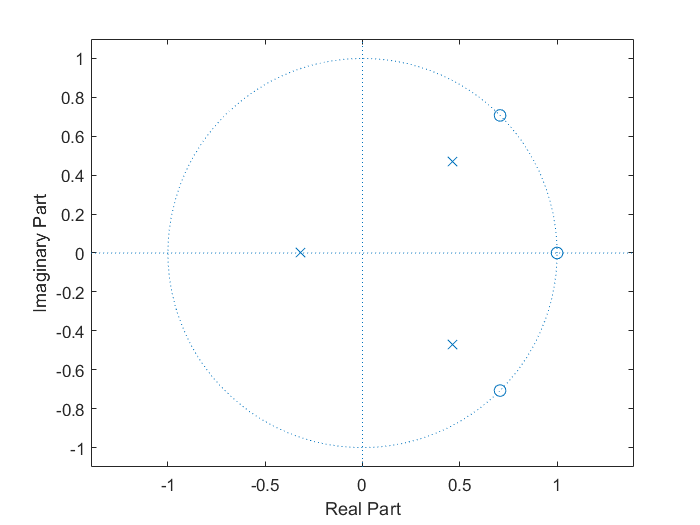


b_min = polystab(b); a_min = polystab(a);
zplane(b_min, a_min);


b_max = fliplr(b_min); a_max = a_min;
zplane(b_max, a_max);

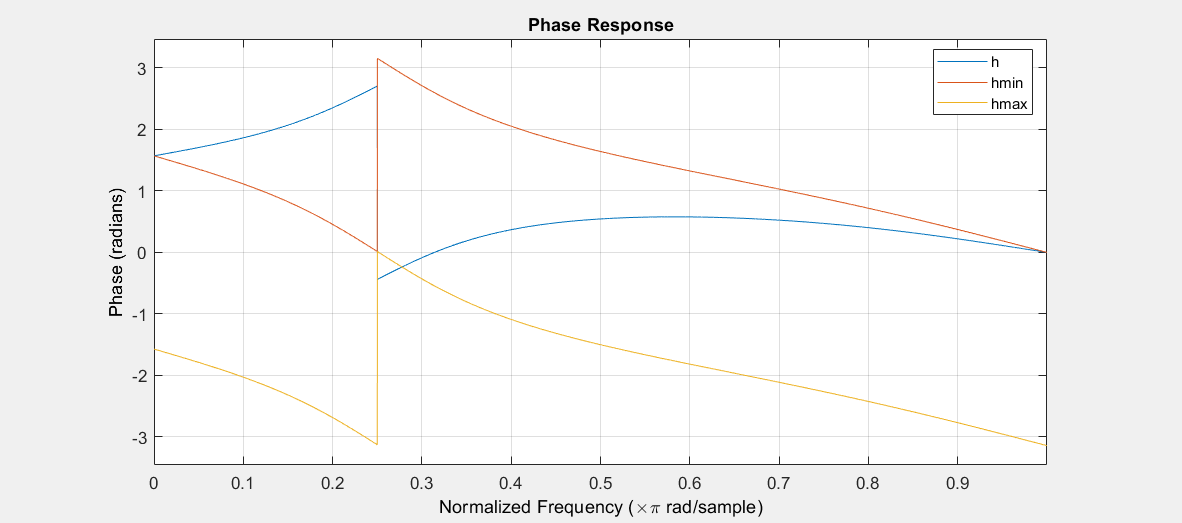


hfvt = fvtool(b, a, b_min, a_min, b_max, a_max,'Analysis','phase');
legend(hfvt,'h','hmin','hmax');

## P11

Signal $x_c \left(t\right)=5\mathrm{cos}\left(200\pi t+\pi 6\right)+4\mathrm{sin}\left(300\pi t\right)$ is sampled at a rate of $F_S =1\mathrm{kHz}$ to obtain 

the discrete-time signal $x\left\lbrack n\right\rbrack$. 

(a) Determine the spectrum $X\left(e^{j\omega } \right)$ of $x\left\lbrack n\right\rbrack$ and plot its magnitude as a function of ω in $\frac{\mathrm{rad}}{\mathrm{sample}}$ and as a function of F in Hz. Explain whether the original signal $x_c \left(t\right)$ can be recovered from $x\left\lbrack n\right\rbrack$. 


$$\omega =2\pi \mathrm{FT}=2\pi \frac{F}{F_s }$$


close all; clear;
fprintf('11(a)\n');

11(a)


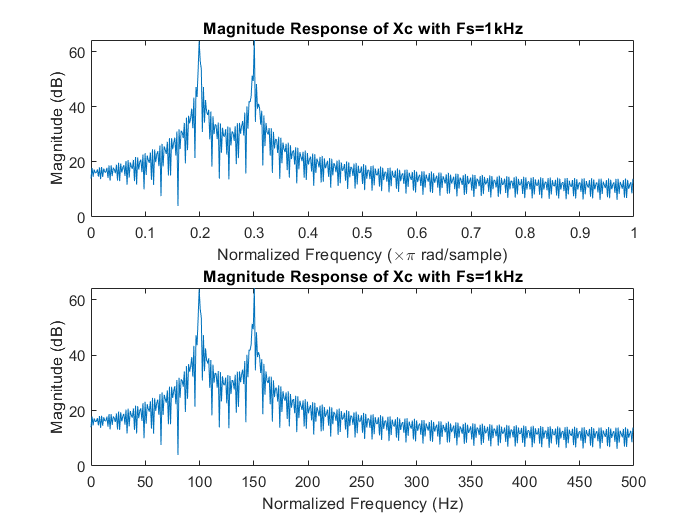


t = 1000; Fs = 1000;
om = linspace(0, t, Fs*t);
x_a = 5*cos(200*pi*om + 6*pi) + 4*sin(300*pi*om);

[h_a, w_a] = freqz(x_a, 1);
figure;
subplot(2,1,1); plot(w_a/pi, 20*log10(abs(h_a)));
title('Magnitude Response of Xc with Fs=1kHz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
subplot(2,1,2); plot(w_a*Fs/(2*pi), 20*log10(abs(h_a)));
title('Magnitude Response of Xc with Fs=1kHz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (Hz)');


% figure; stem((0:length(x_a)-1),x_a);
% title('x_c(t) with Fs=1kHz');
% ylabel('x[n]');
% xlabel('Time index (n)');

The frequency of signals $5\cos \left(200\pi t+\pi 6\right)$ and $4\sin \left(300\pi t\right)$ are 100Hz and 150Hz, respectively. This means that there are peaks in both 100Hz and 150Hz in the frequency domain of the original signal $x_c \left(t\right)$.

Due to sampling theorem, sampling signal can be recovered if the sampling rate ($F_S$) is larger than two times highest frequency in the signal($F_H$), which means that $F_s \ge 2F_H$.

The original signal $x_c \left(t\right)$ can be recovered from $x\left\lbrack n\right\rbrack$ because $F_s =1\mathrm{kHz}\ge 2F_H =2\times \left(150\right)\mathrm{Hz}$.

(b) Repeat part (a) for Fs = 500 Hz. 

fprintf('11(b)\n');

11(b)


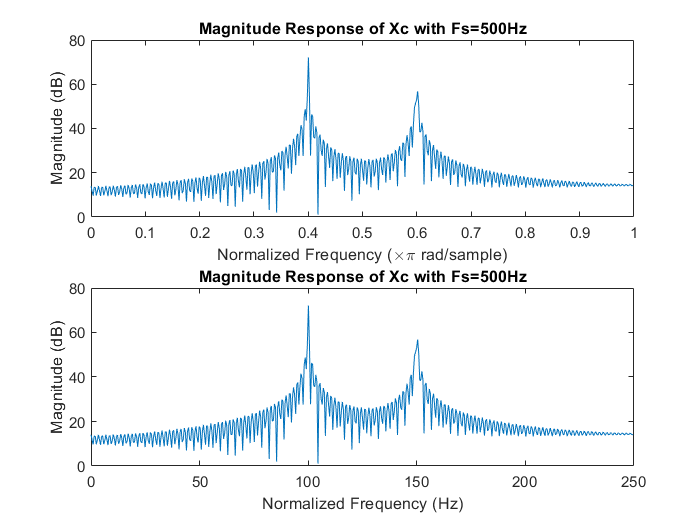


Fs = 500;
om = linspace(0, t, Fs*t);
x_b = 5*cos(200*pi*om + 6*pi) + 4*sin(300*pi*om);

[h_b, w_b] = freqz(x_b, 1);
figure;
subplot(2,1,1); plot(w_b/pi, 20*log10(abs(h_b)));
title('Magnitude Response of Xc with Fs=500Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
subplot(2,1,2); plot(w_b*Fs/(2*pi), 20*log10(abs(h_b)));
title('Magnitude Response of Xc with Fs=500Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (Hz)')

The original signal $x_c \left(t\right)$ can be recovered from $x\left\lbrack n\right\rbrack$ because $F_s =500\textrm{Hz}\ge 2F_H =2\times \left(150\right)\mathrm{Hz}$.

(c) Repeat part (a) for Fs = 100 

fprintf('11(c)\n');

11(c)


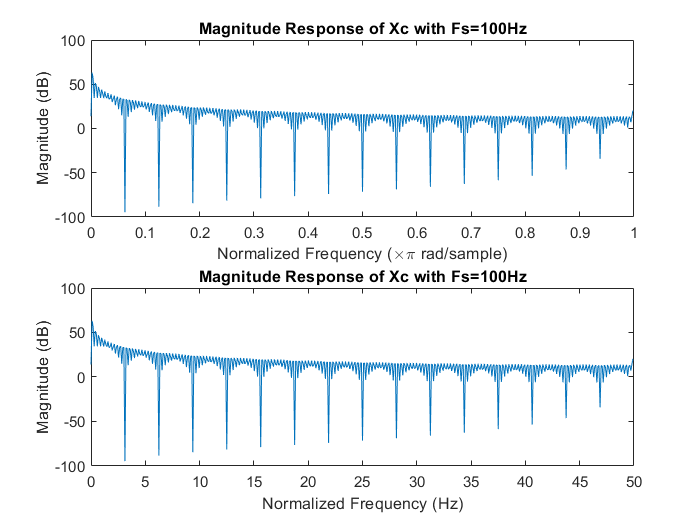


Fs = 100; t = 1000;
om = linspace(0, t, Fs*t);
x_c = 5*cos(200*pi*om + 6*pi) + 4*sin(300*pi*om);

[h_c, w_c] = freqz(x_c, 1);
figure;
subplot(2,1,1); plot(w_c/pi, 20*log10(abs(h_c)));
title('Magnitude Response of Xc with Fs=100Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
subplot(2,1,2); plot(w_c*Fs/(2*pi), 20*log10(abs(h_c)));
title('Magnitude Response of Xc with Fs=100Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (Hz)');

The original signal $x_c \left(t\right)$ can't be recovered from $x\left\lbrack n\right\rbrack$ because $F_s =100\textrm{Hz}<2F_H =2\times \left(150\right)\textrm{Hz}$.

(d) Comment on your results. 

Ans.

The sampling theorem shows that sampling signal can be recovered if $F_s \ge 2F_H$, which $F_H$ is 150Hz in the signal $x_c \left(t\right)$. In the results above, only 11(c) doesn't meet this condition, so we can't see any peak in the plot of magnitude.